
desired_amp = 5;
iterations = 21;

b_vals = linspace(desired_amp, 0, iterations)

b_vals =     5.0000    4.7500    4.5000    4.2500    4.0000    3.7500    3.5000    3.2500    3.0000    2.7500    2.5000    2.2500    2.0000    1.7500    1.5000    1.2500    1.0000    0.7500    0.5000    0.2500         0


a_vals = sqrt(desired_amp.^2 - b_vals.^2)

a_vals =          0    1.5612    2.1794    2.6339    3.0000    3.3072    3.5707    3.7997    4.0000    4.1758    4.3301    4.4651    4.5826    4.6837    4.7697    4.8412    4.8990    4.9434    4.9749    4.9937    5.0000



targets = [a_vals; b_vals] % vector of first harmonics: A1; B1 , A1, B1....

targets =          0    1.5612    2.1794    2.6339    3.0000    3.3072    3.5707    3.7997    4.0000    4.1758    4.3301    4.4651    4.5826    4.6837    4.7697    4.8412    4.8990    4.9434    4.9749    4.9937    5.0000
    5.0000    4.7500    4.5000    4.2500    4.0000    3.7500    3.5000    3.2500    3.0000    2.7500    2.5000    2.2500    2.0000    1.7500    1.5000    1.2500    1.0000    0.7500    0.5000    0.2500         0


mags = zeros(1, iterations);

for r = (1:iterations) % loop to find best control target to minimise forcing amp
    % define inputs and prepare for CBC
    % set initial target
    input.A_desired = targets(1, r);
    input.B_desired = targets(2, r);
    control.k_num = 7;
    control.base_target = zeros(control.k_num, 2); %ref signal
    control.base_target(1,:) = [input.A_desired, input.B_desired];
    
    input.F0 = 1;               % Initial forcing amplitude
    input.w0 = 2 * pi;          % Forcing frequency (rad/s)
    reset_model_setup;


    [input_out, trial_out] = closedloop_test(model, input, trial, control);
    [t_lin, x_lin] = get_last_n_periods(trial_out.t_span, input_out.f_history, 20);
    [A_vec,B_vec] = get_fft_components(t_lin, x_lin, input_out.w0, 7);
    mags(r) = sqrt(sum([A_vec,B_vec].^2, "all"));
    r
end

r = 1

r = 2

r = 3

r = 4

r = 5

r = 6

r = 7

r = 8

r = 9

r = 10

r = 11

r = 12

r = 13

r = 14

r = 15

r = 16

r = 17

r = 18

r = 19

r = 20

r = 21

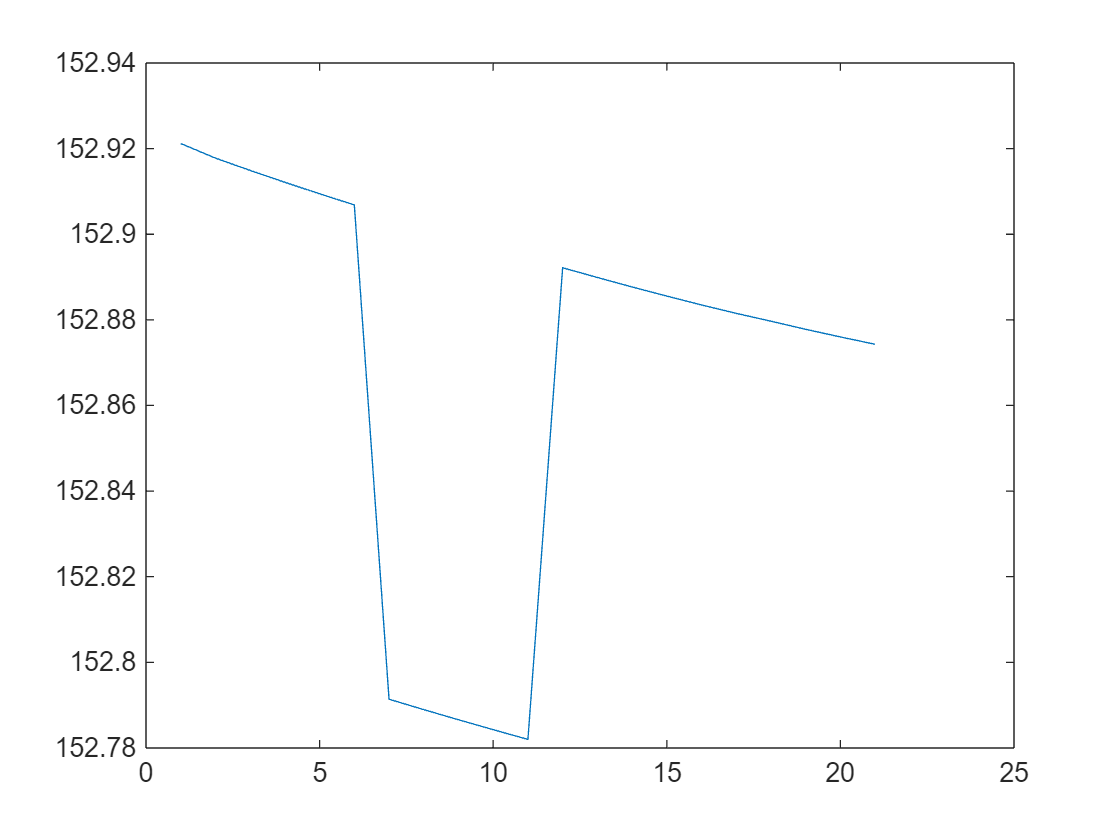

figure;
plot((1:iterations), mags)

[min_val, min_index] = min(mags)

min_val = 152.7820

min_index = 11

input.A_desired = targets(1, min_index)

input = struct with fields:
    A_desired: 4.3301
    B_desired: 0
           F0: 1
           w0: 6.2832
            T: 1
    f_control: 0
    f_history: 0
    e_history: [2×1 double]


input.B_desired = targets(2, min_index)

input = struct with fields:
    A_desired: 4.3301
    B_desired: 2.5000
           F0: 1
           w0: 6.2832
            T: 1
    f_control: 0
    f_history: 0
    e_history: [2×1 double]



control.k_num = 7;
control.base_target = zeros(control.k_num, 2); %ref signal
control.base_target(1,:) = [input.A_desired, input.B_desired];

input.F0 = 1;               % Initial forcing amplitude
input.w0 = 2 * pi;          % Forcing frequency (rad/s)
reset_model_setup;


[input_out, trial_out] = closedloop_test(model, input, trial, control);
[t_lin, x_lin] = get_last_n_periods(trial_out.t_span, input_out.f_history, 20);
[A_vec,B_vec] = get_fft_components(t_lin, x_lin, input_out.w0, 7);
mags(r) = sqrt(sum([A_vec,B_vec].^2, "all"));
r

r = 21

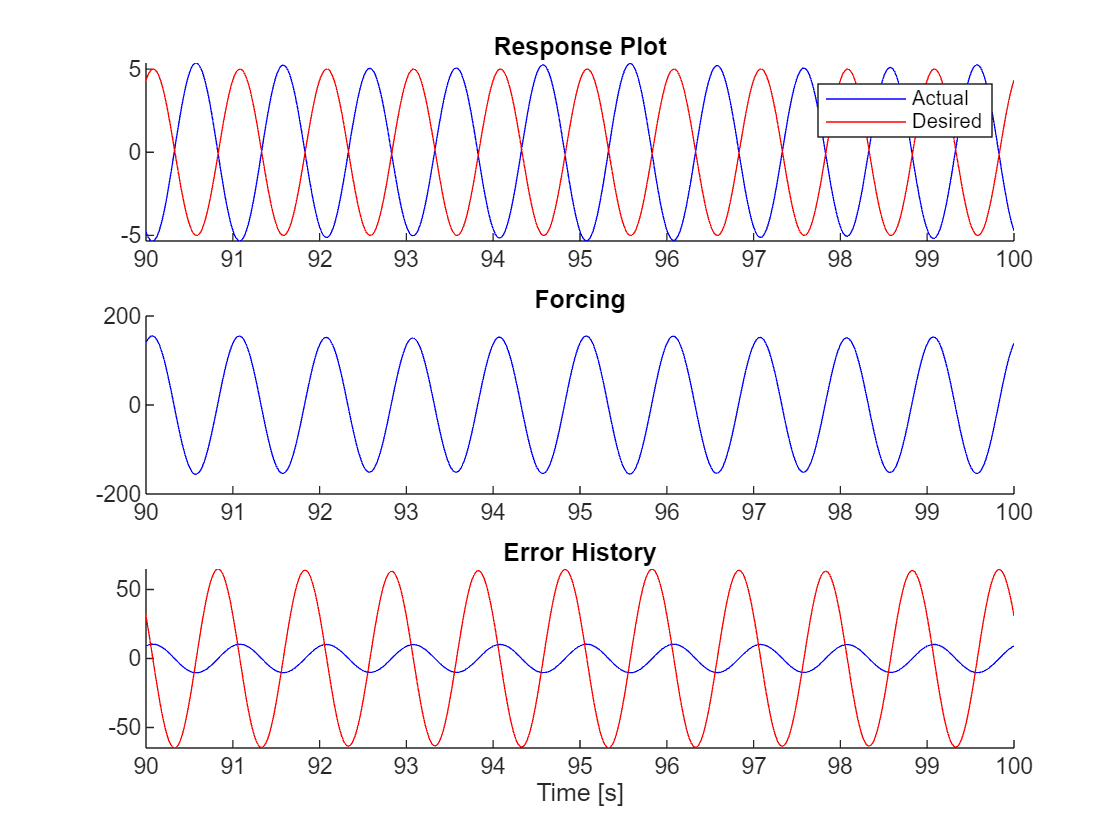


[f] = plot_CL_inner(input_out, trial_out, control);